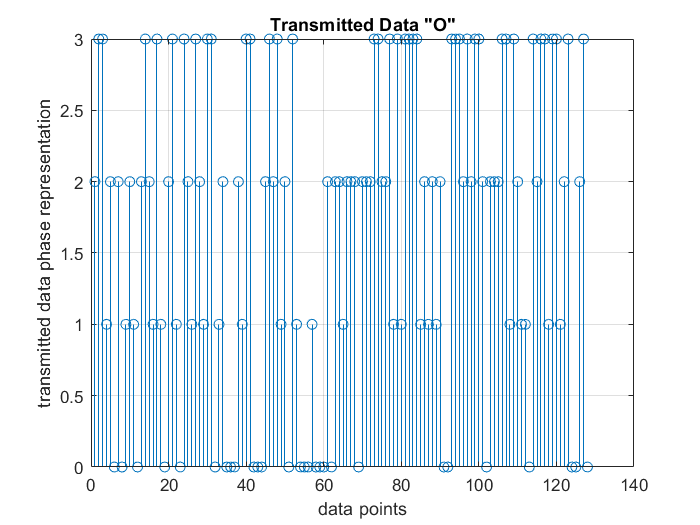


clear scr
clc
%% *************Simulation Parameters***************************

Nsc= 128; % Number of OFDM subcarrier 
Nsd= 110; % number of used sub carrier
Nsp= 18; %number of used pilot sub-carrier
Rcp=1/9; % Overhead of cyclic prefix 
las_width= 5e6; %width of laser OFDM
Rb= 10e9; %Data Rate
Rin= -150; %Relative Intensity noise db/hz
wav= 1550*10^-9; %Wavelength 
G= 10; %preamplifying gain db;
Ge=20; 
n= 0.75; % Effeciency of Photo Diode
Fn= 4.77; %Noise Figure of Optical Amplifier
m = 0.1; %modulation technique
le = 1000; %link length
Tn = 0.9; % Transmitter optical effeciency
Rn= 0.75; %Reciever optical effeienyy 
Tdia = 0.1; %aperture of Tx
Rdia= 5*10^-3; %aperture of Rx
theta= 72*10^-6; % Half Beam divergence angle
coeff= 2; % Attenuation coeffecient for haze atmospheric condition
loss_window= 1; %optical Window loss
loss_pointing= 1; % Pointing loss
Ref_in_mod= 1.7*10^-14;% Refractive index for moderate turbulance
Ref_in_strong= 5*10^-14;% Refractive index for strong turbulance
G_t=8/theta;
G_r=(pi*Rdia/wav)^2;
Pt_av= 300; %Average optical power transmitted (Db)
I=1; % Irradiance
k=1.38*10^-23;
Fn=4.47;
h_upperlimit = 8; %Upperlimit of h
h_lowerlimit = 0; %Lowerlimit of h 
x= 0.01; %Interval of PDF
h= (h_lowerlimit:x:h_upperlimit);
noise_x =(0:0.01:8);

k_beam   = (2*pi)/wav;
Cn_sq    = 1.7e-14;
h_a = exp(coeff*le);
%% *************OFDM Simulation***************************
M = 4;                          %   QPSK signal constellation
no_of_data_points = 128;        %   have 64 data points
block_size = 16;                 %   size of each ofdm block
cp_len = 2;  %   length of cyclic prefix
no_of_ifft_points = block_size;           %   8 points for the FFT/IFFT
no_of_fft_points = block_size;
%%  ---------------------------------------------
%   B:  %   +++++   TRANSMITTER    +++++
%   ---------------------------------------------
%   1.  Generate 1 x 64 vector of data points phase representations
data_source = randsrc(1, no_of_data_points, 0:M-1);
figure(1)
 stem(data_source); grid on; xlabel('data points'); ylabel('transmitted data phase representation')
 title('Transmitted Data "O"')

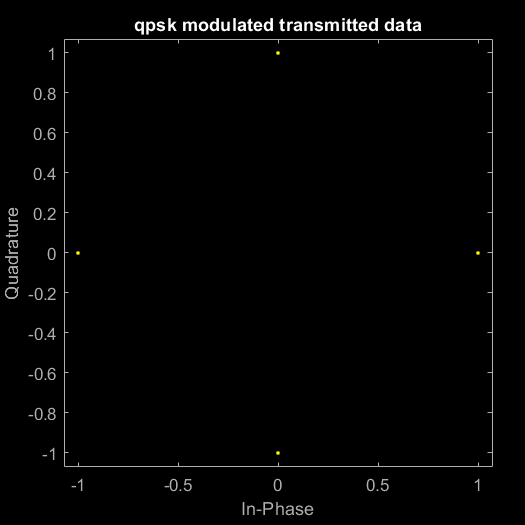

%   2.  Perform QPSK modulation
qpsk_modulated_data = pskmod(data_source, M);
scatterplot(qpsk_modulated_data);title('qpsk modulated transmitted data')

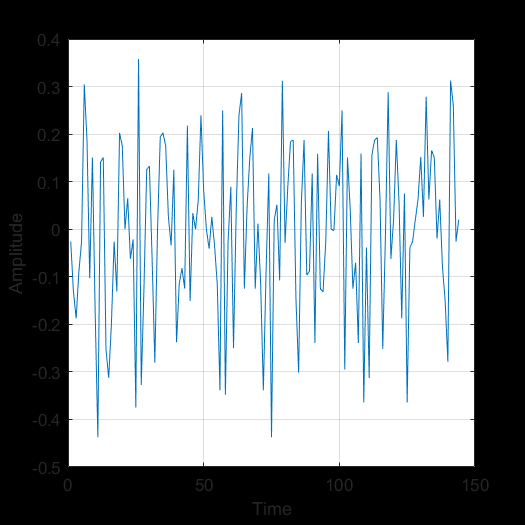

%   3.  Do IFFT on each block
%   Make the serial stream a matrix where each column represents a pre-OFDM
%   block (w/o cyclic prefixing)
%   First: Find out the number of colums that will exist after reshaping
num_cols=length(qpsk_modulated_data)/block_size;
data_matrix = reshape(qpsk_modulated_data, block_size, num_cols);
%   Second: Create empty matix to put the IFFT'd data
cp_start = block_size-cp_len;
cp_end = block_size;
%   Third: Operate columnwise & do CP
for i=1:num_cols,
    ifft_data_matrix(:,i) = ifft((data_matrix(:,i)),no_of_ifft_points);
    %   Compute and append Cyclic Prefix
    for j=1:cp_len,
       actual_cp(j,i) = ifft_data_matrix(j+cp_start,i);
    end
    %   Append the CP to the existing block to create the actual OFDM block
    ifft_data(:,i) = vertcat(actual_cp(:,i),ifft_data_matrix(:,i));
end
%   4.  Convert to serial stream for transmission
[rows_ifft_data cols_ifft_data]=size(ifft_data);
len_ofdm_data = rows_ifft_data*cols_ifft_data;
%   Actual OFDM signal to be transmitted
ofdm_signal = reshape(ifft_data, 1, len_ofdm_data);
figure(3)
 plot(real(ofdm_signal)); xlabel('Time'); ylabel('Amplitude');
title('OFDM Signal');grid on;

P_t=Pt_av*Tn*G_t*(1+(m*ofdm_signal));





%% Gamma-Gamma
sigma_sq = 1.23*Cn_sq*(k_beam^(7/6))*le^(11/6);

dsig    = sqrt((0.25*k_beam*(Rdia)^2)/le);

%beta1 
beta1_Num = 0.51*sigma_sq*(1+(0.69*(sigma_sq)^1.2))^(-5/6);
beta1_Den = 1+(0.9*dsig^2)+(0.62*dsig^2*(sigma_sq)^1.2);

beta1     = ((exp(beta1_Num/beta1_Den))-1)^-1;

%alpha1
alpha1_Num= 0.49*sigma_sq;
alpha1_Den= (1+(0.65*dsig^2)+(1.11*(sigma_sq)^1.2))^(7/6);

alpha1    = ((exp(alpha1_Num/alpha1_Den))-1)^-1;
GGpdf_h = zeros(1,length(h));

for i = 1:length(h)
    GGpdf_h(i) = PGG2(alpha1,beta1,h(i));
end

----------------
h cannot be zero
----------------


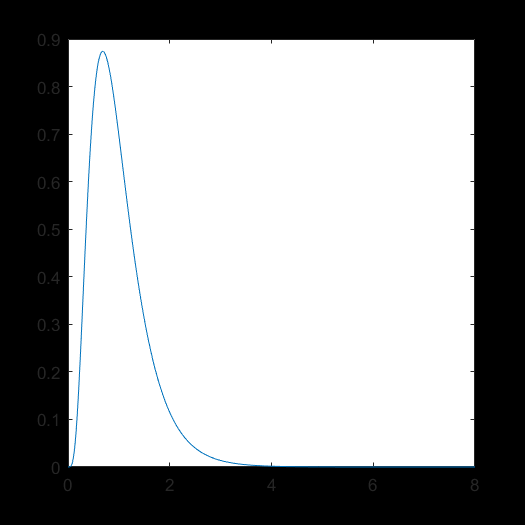

figure(6)
plot(h,GGpdf_h)

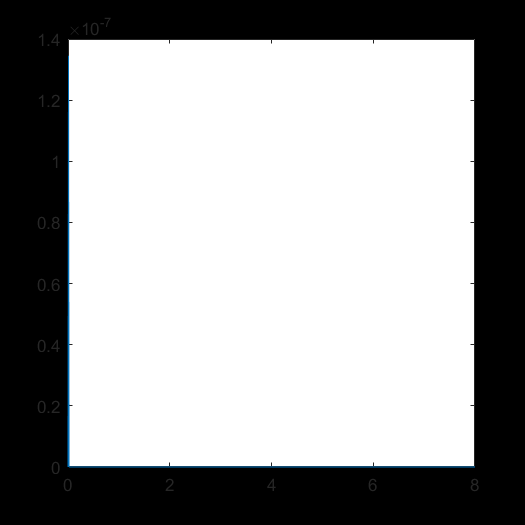


%% Noise
SNR_dB=40; %SNR value in dB
SNR=10.^(SNR_dB./10);
 h2=h.^2;
 
%  SNR= SNR.*h2;
Noise_var_pdf=Pt_av/SNR.*h2;
Noise_var=trapz(h,Noise_var_pdf.*GGpdf_h);
noise_pdf = raylpdf(noise_x,Noise_var.^2);
plot(noise_x,noise_pdf)



%% SNR and BER
Snr_th= 15;
SNR_th=10.^(Snr_th./10);
%   SNR_th= SNR_th.*h2;
N0= Pt_av/SNR_th.*h2;

for i=1:length(h2)
    [c limit]=  min(abs(noise_pdf-N0(i)));
    if limit==1
        stp(i)=0;
    else
        stp(i)= trapz(h(1:limit),noise_pdf(1:limit));
    end
end
STP= trapz(h,stp.*GGpdf_h)

STP =      1.289017556715107e-09


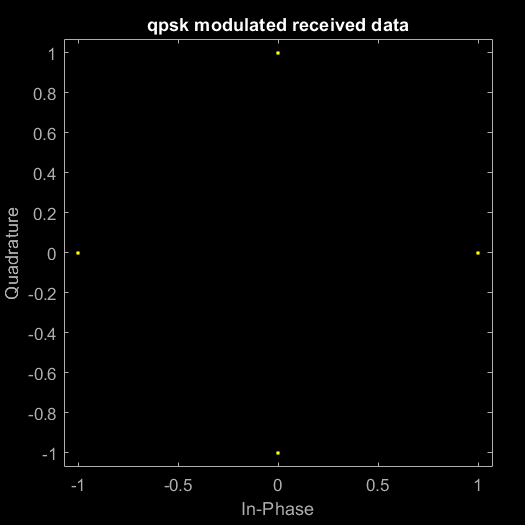

 
%% STP Calculation

%   for i= 1:length(h2)
%       STP[i]= trapz(GGpdg_h).*
%   end
  
%%
%   ------------------------------------------
%   E:  %   +++++   RECEIVER    +++++
%   ------------------------------------------
 
P_r=P_t*n*G_r*((wav/4*pi*le)^2)*I;
p_d=((m*G*Ge*Tn*Rn*G_t*G_r*Pt_av*((wav/4*pi*le)^2)*I)^2);


%   1.  Pass the ofdm signal through the channel
recvd_signal = ofdm_signal;
%   4.  Convert Data back to "parallel" form to perform FFT
recvd_signal_matrix = reshape(recvd_signal,rows_ifft_data, cols_ifft_data);
%   5.  Remove CP
recvd_signal_matrix(1:cp_len,:)=[];
%   6.  Perform FFT
for i=1:cols_ifft_data,
    %   FFT
    fft_data_matrix(:,i) = fft(recvd_signal_matrix(:,i),no_of_fft_points);
end
%   7.  Convert to serial stream
recvd_serial_data = reshape(fft_data_matrix, 1,(block_size*num_cols));
%   8.  Demodulate the data
qpsk_demodulated_data = pskdemod(recvd_serial_data,M);
scatterplot(qpsk_modulated_data);title('qpsk modulated received data')

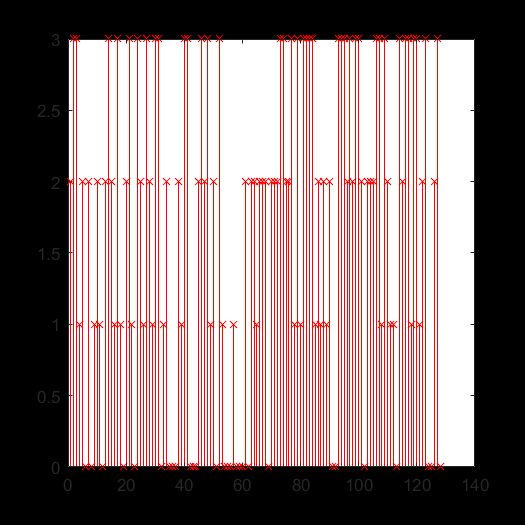

 figure(5)
stem(qpsk_demodulated_data,'rx');

% grid on;xlabel('data points');ylabel('received data phase representation');title('Received Data "X"')  
